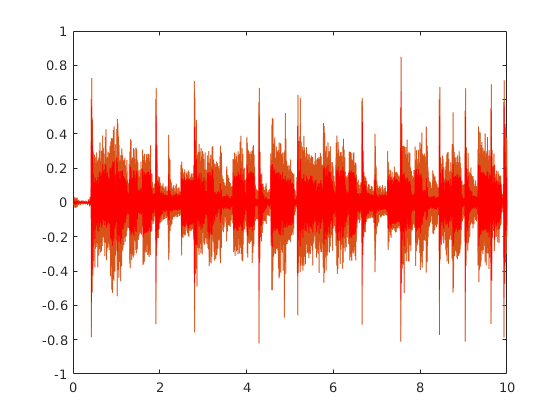

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%Part 3%%%%%%%%%%%%%%%%%%%%%%%
%dir = ''; %directory of file
file = 'song_original.wav';
% song_file = [dir file];
[y,Fs] = audioread(file);
signal = y;
% sound(signal,Fs)


%%%Section 1 - Low and High pass filters%%%%%

%% filter signal
filtered = filter1('lp',signal,'fc',200,'fs',Fs);  %low pass with fc = 200Hz;
%filtered = filter1('hp',signal,'fc',2000,'fs',Fs);  %high pass with fc = 2000Hz;
t = (1:1:size(y,1)).*(1/Fs);
figure(1)  %Plot original and filtered signals
plot(t,y)
hold on
plot(t,signal)
hold on
plot(t,filtered,'r')
hold off

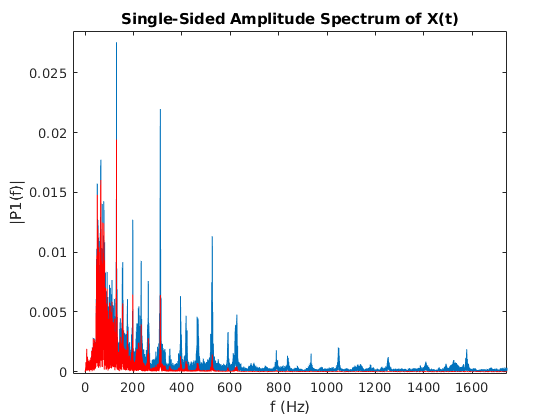


%% Play the songs
% sound(filtered,Fs)
% audiowrite('downsample2_high.wav', filtered, Fs)
%%Use 'clear sound' in the command window to stop playing



%%%%% Section 2 - Downsampling
tstart = 1/Fs;  %starting time
istart = tstart*Fs;
tend = 10;
iend = tend*Fs;
mono = sum(signal,2)/size(signal,2);  %make mono channel
signal = mono(istart:iend); %cut to time given
n=2; %sets down sample
Fs = Fs/n;
signal = downsample(signal,n);
%sound(signal,Fs)
% audiowrite('songTwo_original.wav',signal,Fs);


%%%%Section 3 - FFT and response %%%%%%

%% Plot Freq Response
T = 1/Fs;             % Sampling period       
L = size(signal,1);             % Length of signal

Y = fft(signal);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;

figure(2)
plot(f,P1) 
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')


Y = fft(filtered);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;

hold on
plot(f,P1,'r') 

xlim([-50 1744])
ylim([-0.0002 0.0285])